In addition to typical data analysis, MATLAB is well-suited to image analysis due to its matrix operations. In this section we will explore some of its mapping capabilities and image analysis functions. Whilst other forms of software are useful for image analysis, MATLAB has some additional benefits, one of which is the reproducibility of maps created and analysis that you undertake, also enabling a reader to produce a map and explore it dynamically. Let's start by using some Landsat 8 imagery downloaded from [GloVis](https://glovis.usgs.gov/app?fullscreen=0) of a study site in the UK. We will first download the required datasets:

dirIn = 'C:\_git_local\GEO8026_21_22\Block 05\data\esk\'; % modify as required to point to the git folder
addpath(genpath( 'C:\_git_local\GEO8026_21_22\Block 05\code'));

Let's plot the raw imagery without any manipulation of the bands

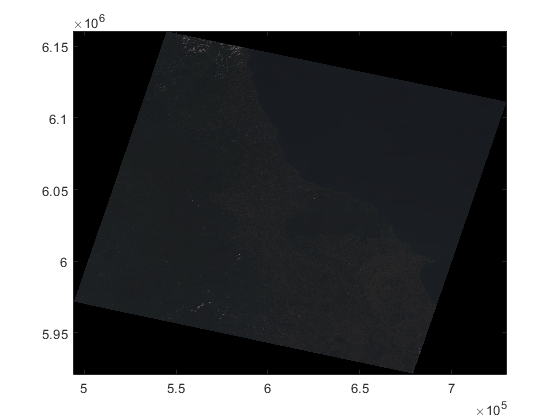

filename = ...
    'LC08_L1TP_203022_20210907_20210916_01_T1_';
channels = ['B4';'B3';'B2';'B5']; % red, green, blue, nir
extension = '.TIF';

[B4,R]  = readgeoraster([dirIn, filename,channels(1,:),extension]); % read georaster can read in geotiff files
[B3]    = readgeoraster([dirIn, filename,channels(2,:),extension]);
[B2]    = readgeoraster([dirIn, filename,channels(3,:),extension]);
[B5]    = readgeoraster([dirIn, filename,channels(4,:),extension]);
[x,y]   = pixcenters(R,R.YIntrinsicLimits(2),R.XIntrinsicLimits(2));

% RGB conversions for display purposes:
bands{1} = im2double(B4);   % Red channel
bands{2} = im2double(B3);   % Green channel
bands{3} = im2double(B2);   % Blue channel

RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

figure();
h2 = image(x,y,RGBImage);  
set(gca, 'YDir','normal');

As you can see, the image is very dark. This is because the histogram is not optimised for visualisation purposes. Let's look at the histogram of the rgb values:

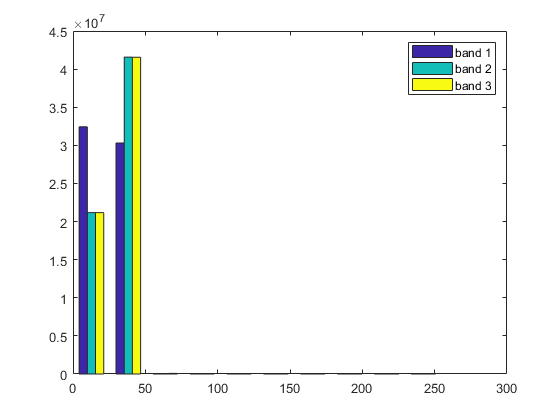


out(:,1) = double(reshape(RGBImage(:,:,1),[],1));
out(:,2) = double(reshape(RGBImage(:,:,2),[],1));
out(:,3) = double(reshape(RGBImage(:,:,3),[],1));
hist(out);
legend('band 1', 'band 2', 'band 3');

We can see that all of the values are skewed to the left of the scale (i.e. < 50), whereas the range of possible color values spans from 0 - 255. We can modify the distribution to improve the way that the image looks:

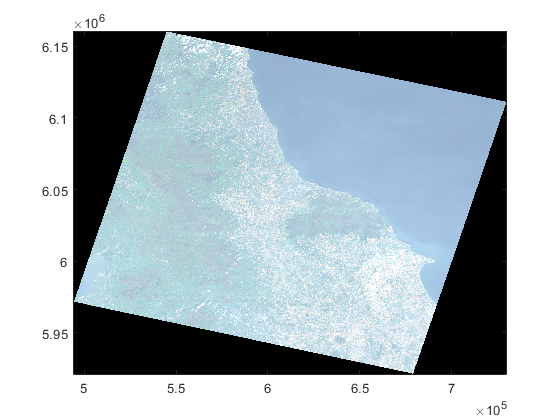

bands{1} = imadjust(bands{1}, stretchlim(bands{1}));       % Adjustment on Red channel
bands{2} = imadjust(bands{2}, stretchlim(bands{2}));       % Adjustment on Green channel
bands{3} = imadjust(bands{3}, stretchlim(bands{3}));       % Adjustment on Blue channel

RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

figure();
h2 = image(x,y,RGBImage);  
set(gca, 'YDir','normal')

This looks a lot better but from the histogram we can see that the values are now skewed to the right. Let's try one more command:


bands{1} = histeq(bands{1});                               % histeq on Red channel
bands{2} = histeq(bands{2});                               % histeq on Green channel
bands{3} = histeq(bands{3});                               % histeq on Blue channel

RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

out(:,1) = double(reshape(RGBImage(:,:,1),[],1));
out(:,2) = double(reshape(RGBImage(:,:,2),[],1));
out(:,3) = double(reshape(RGBImage(:,:,3),[],1));
hist(out)
legend('band 1', 'band 2', 'band 3')
hold off;

Now the image is the way that we want it to look, we can bring in additional features, for example ESRI shapefiles. We just need to make sure that they are in the same projected coordinate system. In this case, both the imagery and shapefiles are in UTM Zone 30N:

figure(); hold on;
h2 = image(x,y,RGBImage);  
set(gca, 'YDir','normal');

x_lims = [624800 658300];
y_lims = [6023500,6042900];
axis equal
set(gca,'xlim',x_lims);
set(gca,'ylim',y_lims);

S = shaperead([dirIn, '\catchment_utm.shp']); % Load in the catchment outline
h1 = plot(S.X,S.Y,'w'); hold on % Plot the catchment outline;
set(h1,'LineWidth',2);
S2 = shaperead([dirIn, '\drainage_utm.shp']); % Load in the river network
for a = 1:length(S2)
    h2 = plot(S2(a).X,S2(a).Y,'b'); set(h2,'LineWidth',3); % Plot the river network
end

hXlabel = xlabel('UTM Zone 30N Eastings [m]'); % Create xlabel
hYlabel = ylabel('UTM Zone 30N Northings [m]'); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);

There are many satellite products that can be used for your analysis. Sentinel 2 is one of the highest resolutions satellite datasest that are freely available to use. We will download this data from the [Copernicus hub](https://scihub.copernicus.eu/dhus/#/home). Let's have a look to see what we can do with this data. 

**This is not longer working and needs checking/fixing**

dirIn_p1 = 'C:\_git_local\GEO8026_21_22\Block 05\data\kenya\'; % modify as required
dirIn_p2 = 'S2B_MSIL1C_20210824T074609_N0301_R135_T36MZE_20210824T094911.SAFE\GRANULE\L1C_T36MZE_A023327_20210824T080452\IMG_DATA\'

dirIn_p2 = 'S2B_MSIL1C_20210824T074609_N0301_R135_T36MZE_20210824T094911.SAFE\GRANULE\L1C_T36MZE_A023327_20210824T080452\IMG_DATA\'

dirIn       = [dirIn_p1 dirIn_p2];

filename = ...
    'T36MZE_20210824T074609_';
channels = ['B04';'B03';'B02';'B08']; % r g b ir
extension = '.jp2';

[B4,x,y,I]  = geoimread([dirIn, filename,channels(1,:),extension]);
[B3,~, ~,~] = geoimread([dirIn, filename,channels(2,:),extension]);
[B2,~, ~,~] = geoimread([dirIn, filename,channels(3,:),extension]);
[B8,~, ~,~] = geoimread([dirIn, filename,channels(4,:),extension]);
idx         = find(B4 == 0 & B3 == 0 & B2 == 0 & B8 == 0 ); % find cells with no data on any of the channels

% Calculate the NDVI + plot the results
NDVI        = (single(B8) - single(B4))./ (single(B8) + single(B4));
NDVI(idx)	= NaN;
figure(); hold on
h0          = imagesc(x,y,NDVI); 
hold off

% Calculate the NDWI
NDWI    = (single(B3) - single(B8)) ./ (single(B3) + single(B8));
NDWI(idx) = NaN;
figure(); hold on
h1      = imagesc(x,y,NDWI);      
hold off


% RGB conversions for display purposes:
bands{1} = im2double(B4);   % Red channel
bands{2} = im2double(B3);   % Green channel
bands{3} = im2double(B2);   % Blue channel

bands{1} = imadjust(bands{1}, stretchlim(bands{1}));       % Adjustment on Red channel
bands{2} = imadjust(bands{2}, stretchlim(bands{2}));       % Adjustment on Green channel
bands{3} = imadjust(bands{3}, stretchlim(bands{3}));       % Adjustment on Blue channel

RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

figure();
h1 = image(x,y,RGBImage);        

Finally, one of the more recent resources that has been made available is a commerical product from PlanetLabs. However, these are also freely accessible for research use Let's start by plotting the imagery:

dirIn = 'C:\_git_local\GEO8026_21_22\Block 05\data\iceland\iceland1_psscene4band_analytic_sr_udm2\files\PSScene4Band\20210816_114330_01_2440\analytic_sr_udm2\';
filename = ...
    '20210816_114330_01_2440_3B_AnalyticMS_SR';
extension = '.TIF';

[Bin,R]     = readgeoraster([dirIn, filename,extension]);
[x,y]       = pixcenters(R,abs(R.YIntrinsicLimits(2)-R.YIntrinsicLimits(1)),...
    abs(R.XIntrinsicLimits(2)-R.YIntrinsicLimits(1)));

% RGB conversions for display purposes:
bands{1} = Bin(:,:,3);   % Red channel
bands{2} = Bin(:,:,2);   % Green channel
bands{3} = Bin(:,:,1);   % Blue channel
bands{4} = Bin(:,:,4);   % NIR channel

% Optimise the bands for display
bands{1} = imadjust(bands{1}, stretchlim(bands{1}));       % Adjustment on Red channel
bands{2} = imadjust(bands{2}, stretchlim(bands{2}));       % Adjustment on Green channel
bands{3} = imadjust(bands{3}, stretchlim(bands{3}));       % Adjustment on Blue channel

% We won't run the hist equalisation for this data as the visuals are okay
% without it

RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

figure(); hold on;
h0 = image(x,y,RGBImage); 

hXlabel = xlabel('UTM Zone 28N Eastings [m]'); % Create xlabel - the defined CRS can be found in the variable R.R.ProjectedCRS
hYlabel = ylabel('UTM Zone 28N Northings [m]'); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
hold off


We can also calculate metrics from the data. We'll calculate the NDWI  and plot the results:


% find cells with no data
idx      = find(bands{1} == [29127] & bands{2} == [29127] & ...
    bands{3} == [29127] & bands{4} == [0] ); % find cells with no data

% calcuate the ndwi
NDWI    = (single(bands{2}) - single(bands{4} )) ./ (single(bands{2}) + single(bands{4} ));
NDWI(idx) = NaN;

% Plot the results
h1      = imagesc(x,y,NDWI);     
c1      = colorbar
ylabel(c1, 'NDWI index')

hXlabel = xlabel('UTM Zone 28N Eastings [m]'); % Create xlabel - the defined CRS can be found in the variable R.R.ProjectedCRS
hYlabel = ylabel('UTM Zone 28N Northings [m]'); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
set(gca, 'YDir','normal');



Now let's try and run the same analysis for the sandur where it reaches the sea:


dirIn = 'C:\Users\Matt\OneDrive - Newcastle University\Teaching\2021 - 22\GEO8026\Block 05\data\iceland\iceland1_psscene4band_analytic_sr_udm2\files\PSScene4Band\20210816_114334_96_2440\analytic_sr_udm2\';
filename = ...
    '20210816_114334_96_2440_3B_AnalyticMS_SR';
extension = '.TIF';

[Bin,R]     = readgeoraster([dirIn, filename,extension]);
[x,y]       = pixcenters(R,abs(R.YIntrinsicLimits(2)-R.YIntrinsicLimits(1)),...
    abs(R.XIntrinsicLimits(2)-R.YIntrinsicLimits(1)));

% RGB conversions for display purposes:
bands{1} = Bin(:,:,3);   % Red channel
bands{2} = Bin(:,:,2);   % Green channel
bands{3} = Bin(:,:,1);   % Blue channel
bands{4} = Bin(:,:,4);   % NIR channel

% Optimise the bands for display
bands{1} = imadjust(bands{1}, stretchlim(bands{1}));       % Adjustment on Red channel
bands{2} = imadjust(bands{2}, stretchlim(bands{2}));       % Adjustment on Green channel
bands{3} = imadjust(bands{3}, stretchlim(bands{3}));       % Adjustment on Blue channel

% We won't run the hist equalisation for this data as the visuals are okay
% without it

RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

figure(); hold on;
h0 = image(x,y,RGBImage); 

hXlabel = xlabel('UTM Zone 28N Eastings [m]'); % Create xlabel - the defined CRS can be found in the variable R.R.ProjectedCRS
hYlabel = ylabel('UTM Zone 28N Northings [m]'); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
hold off


We can also calculate metrics from the data. We'll calculate the NDWI  and plot the results:


% find cells with no data
idx      = find(bands{1} == [29127] & bands{2} == [29127] & ...
    bands{3} == [29127] & bands{4} == [0] ); % find cells with no data

% calcuate the ndwi
NDWI    = (single(bands{2}) - single(bands{4} )) ./ (single(bands{2}) + single(bands{4} ));
NDWI(idx) = NaN;

% Plot the results
figure(); hold on;
h1      = imagesc(x,y,NDWI);     
c1      = colorbar;
ylabel(c1, 'NDWI index')

hXlabel = xlabel('UTM Zone 28N Eastings [m]'); % Create xlabel - the defined CRS can be found in the variable R.R.ProjectedCRS
hYlabel = ylabel('UTM Zone 28N Northings [m]'); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
set(gca, 'YDir','normal');

th      = 0.94;
a       = NDWI(:,:,1) > th; % find pixel values greater than 0.97
a       = bwareaopen(a,100,4); % find 50+ connected pixels
B       = bwboundaries(a,'noholes');


warning('off')
for c = 1:length(B)
    filled  = polyshape (B{c,1}(:,1),B{c,1}(:,2)); % polyshape
    if ~isempty(filled.Vertices(:,1))
        temp1   = [filled.Vertices(:,1),filled.Vertices(:,2)];
        isx     = find(~isnan(temp1(:,1)));
        dataIn  = [temp1(isx,1),temp1(isx,2)];
        filled.Vertices(isx,1:2) = [x(dataIn(:,2));y(dataIn(:,1))]'; % check why it is y then x???
        plot(filled,'FaceColor','k','FaceAlpha',0.5); hold on;
    end
end
